# Reinforcement Learning for Closed Loop Control of Q Tank Process

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction

In the previous lesson, we have learnt about the actor critic network in detail. Now we apply it to the Q tank Process. The [Q tank process simulink model ](matlab:open('../2.Dynamical_Control_and_Models/L05_Nonlinearity_of_MVProcess.mlx'))which has been studied earlier, is used as a process in this exercise. The same simulink model is used in this exercise.

**Learning Objectives**

- To develop actor critic network  and apply it to the Q tank Process

- To create and train the DDPG  agent for a Q tank system using Simulink.

## Q Tank Example

This model already contains an RL Agent block, which connects to the following signals:

- Scalar action output signal

- Vector of observation input signals

- Scalar reward input signal

- Logical input signal for stopping the simulation and

- Q tank Process Open Loop Model 

which is combinedly named as "fourtank_RLModel". 

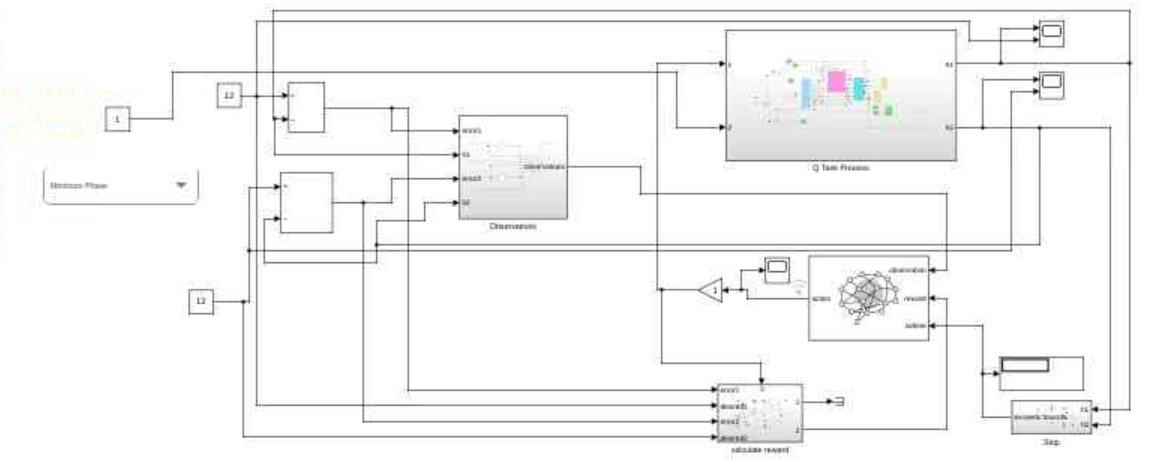

open_system("fourtank_RLModel")

**Actions and Observations**

A reinforcement learning environment receives action signals from the agent and generates observation signals in response to these actions. To create and train an agent, we first create action and observation specification objects.

The action signals for this environment are the flow rates. To create a specification object for an action channel carrying a continuous signal, use `rlNumericSpec`. Define the observation specification obsInfo and action specification actInfo.

We define action info as `rlNumericSpec[2 1]`` for the two input flows`

actInfo = [
    rlNumericSpec([2 1], Name="actInLyr");
];

For this example, we have used three observation signals corresponding to  each level output which are sent to the agent, specified as a vector signal. The observation vector is ${\left\lbrack \int \textrm{edt}\;\;e\;\;h\right\rbrack }^T$ , where:

- *h* is the level of the water in the tank.

- *e*=*r*−*h*, where *r* is the desired value for the water level.

We have created **observations subsystem** to compute the Compute the observation signals in the above manner. 

obsInfo = [
    rlNumericSpec([6 1], Name="obsInLyr");
 ];
open_system("fourtank_RLModel" + "/Observations")
env = rlSimulinkEnv( "fourtank_RLModel", "fourtank_RLModel/RL Agent",obsInfo,actInfo);

### **Reward Signal**

We need to construct a scalar reward signal. For this example, we have used the following reward.


$$r\left(k\right)=\sum_{j=1}^l e^{-0\ldotp 5{\left(\frac{-e_j \left(k\right)}{\beta_j r_{\textrm{sp},j} \left(k\right)}\right)}^2 }$$


where $e_j \left(k\right)$=$r_{\textrm{sp},j} \left(k\right)-y_j \left(k\right)$ , $r_{\textrm{sp},j} \left(k\right)$---desired level and $y_j \left(k\right)$-measured level 

${0<\beta }_j <1$ penalty factor to pennalize the error. This reward is calculated in a **"Calculate Reward" **subsystem**.** 

### Reset Operation

Set a custom reset function that randomizes the reference values for the model. This function is given at the end

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time Tf and the agent sample time Ts in seconds.

Ts = 1.0;
Tf = 500;

Fix the random generator seed for reproducibility.

rng(0)

## Create the Critic

DDPG agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by obsInfo, and the other for the action channel, as specified by actInfo) and one output layer (which returns the scalar value).

In the critic network, there will be three paths:

- Observation path

- Action path and 

- Common path

Each of the network paths are array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel. The dimension of the observation and action spaces are obtained  from the **obsInfo** and **actInfo** specifications. Thus the observation path has input layer with 6 layers corresponding to 6 observations and 2 input layers in action path. 

### **Observation Path**

obsPath = [
    featureInputLayer(6,Name="obsInLyr")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(25,Name="obsPathOutLyr")
    ]

obsPath =   4x1 Layer array with layers:

     1   'obsInLyr'        Feature Input     6 features
     2   ''                Fully Connected   50 fully connected layer
     3   ''                ReLU              ReLU
     4   'obsPathOutLyr'   Fully Connected   25 fully connected layer

### ** Action path**

actPath = [
    featureInputLayer(2,Name="actInLyr")
    fullyConnectedLayer(25,Name="actPathOutLyr")
    ]

actPath =   2x1 Layer array with layers:

     1   'actInLyr'        Feature Input     2 features
     2   'actPathOutLyr'   Fully Connected   25 fully connected layer

### ** Common path**

commonPath = [
    concatenationLayer(1, 2, Name="concat")
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(1, Name="QValue")
]

commonPath =   4x1 Layer array with layers:

     1   'concat'   Concatenation     Concatenation of 2 inputs along dimension 1
     2   ''         Fully Connected   64 fully connected layer
     3   ''         ReLU              ReLU
     4   'QValue'   Fully Connected   1 fully connected layer

** Create the network object and add the layers as per above created paths**

criticNet = dlnetwork()

criticNet =   dlnetwork with properties:

         Layers: [0x1 nnet.cnn.layer.Layer]
    Connections: [0x2 table]
     Learnables: [0x3 table]
          State: [0x3 table]
     InputNames: {1x0 cell}
    OutputNames: {1x0 cell}
    Initialized: 0

  View summary with summary.


criticNet =  addLayers(criticNet, obsPath);
criticNet = addLayers(criticNet, actPath);
criticNet = addLayers(criticNet, commonPath);
criticNet = connectLayers(criticNet,"obsPathOutLyr","concat/in1");      % relu from obsPath
criticNet= connectLayers(criticNet, "actPathOutLyr","concat/in2");    % relu from actPath

View the critic network configuration. We use a function plot to view this

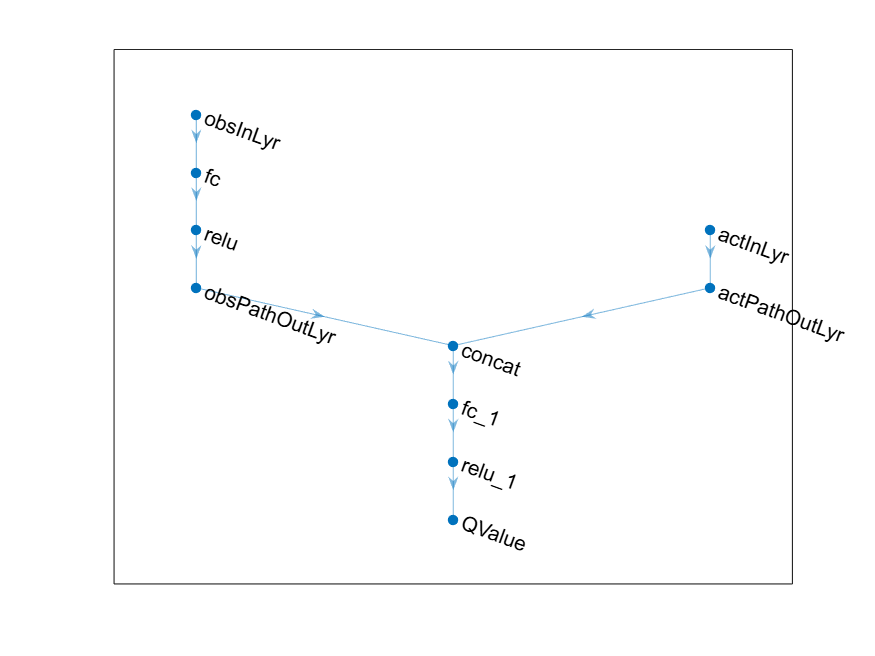

plot(criticNet)

Initialize the dlnetwork object "criticNet" using initialize command and summarize its properties using matlab function summary.

criticNet = initialize(criticNet);
summary(criticNet)


   Initialized: true

   Number of learnables: 5k

   Inputs:
      1   'obsInLyr'   6 features
      2   'actInLyr'   2 features



### Q-value function

Q-value function represents the **expected cumulative reward** an agent can obtain **starting from a given state and taking a specific action**, while following a certain policy thereafter.

Mathematically, the Q-value function is defined as:


$$Q\left(s,a\right)=\mathbb{E}\left|R_t \right|$$


- $Q\left(s,a\right)$ = expected total reward from state sss after taking action aaa,

- $R_t$ = future cumulative reward,

- The expectation $\mathbb{E}\left|R_t \right|$ accounts for uncertainties in the environment.

Q-Value Function is Important as it 

- **Helps the agent evaluate actions** before taking them.

- **Used in value-based RL** methods (like DQN).

- **Improves policy updates** in actor-critic methods (like DDPG & TD3).

We now create the **critic approximator object** using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels. We use **rlQValueFunction** here. 

critic = rlQValueFunction(criticNet, obsInfo, actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr")

critic =   rlQValueFunction with properties:

    ObservationInfo: [1x1 rl.util.rlNumericSpec]
         ActionInfo: [1x1 rl.util.rlNumericSpec]
      Normalization: ["none"    "none"]
          UseDevice: "cpu"
         Learnables: {10x1 cell}
              State: {0x1 cell}


 Check the critic with a random input observation and action.

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
-0.2319

## Create the Actor

In reinforcement learning, the **actor** is the part of the agent that **chooses actions** based on the current **observations** (states). In simple words, the **actor** *decides* what action to take. 

- An **actor** is usually implemented as a **neural network**.

- This **actor network** learns a **policy** $\pi \left(s\right)$ that tells the agent which action to take for each state.

We Define the Actor network as an array of layer objects.

actorNet = [
    featureInputLayer(6,Name="obsInLyr")
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(2,Name="actInLyr")
    ];

We convert the network to a dlnetwork object and summarize its properties.

actorNet = dlnetwork(actorNet);
summary(actorNet)


   Initialized: true

   Number of learnables: 29

   Inputs:
      1   'obsInLyr'   6 features



Now we create the actor approximator object using the specified deep neural network, the environment specification objects, and the name if the network input to be associated with the observation channel. 

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

Let us now Check the actor with a random input observation.

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1x1 cell array
    {2x1 single}


## Create the DDPG Agent

**DDPG** stands for **Deep Deterministic Policy Gradient**. It’s an advanced **model-free** reinforcement learning algorithm designed for **continuous action spaces-** meaning when the actions aren't simple choices (like left or right), but **real numbers** (like valve opening percentage, voltage levels, motor speeds, etc.).

DDPG combines ideas from:

- **DQN** (Deep Q Networks, value-based)

- **Policy Gradient** (actor-based learning)

and works using an **Actor-Critic** architecture. The actor selects an action based on the current observation. Critic evaluates how good the action is by estimating Q-values. The replay buffer stores past experiences and reuses them for training (to break correlation and improve stability).

-  **Actor** learns the **best policy**.

-  **Critic** learns to **predict the value** of actions.

At each step:

- The actor suggests an action.

- The critic tells how good that action is.

- Both networks are improved using gradients based on their performance.

We now create the **DDPG agent **using the specified actor and critic approximator objects.

agent = rlDDPGAgent(actor,critic)

agent =   rlDDPGAgent with properties:

        ExperienceBuffer: [1x1 rl.replay.rlReplayMemory]
            AgentOptions: [1x1 rl.option.rlDDPGAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1x1 rl.util.rlNumericSpec]
              ActionInfo: [1x1 rl.util.rlNumericSpec]
              SampleTime: 1


**Agent Options** are a set of settings that define: 

- How the agent trains (learning rates, exploration noise, mini-batch size)

- How the networks update

- How much exploration vs. exploitation the agent does

- How big the replay buffer is

- Many other training and simulation behaviors

They **control the internal behavior** of the agent without changing the main actor-critic structure.

Specify options for the agent, the actor, and the critic using dot notation.

agent.SampleTime = Ts;
agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e6; 
agent.AgentOptions.NoiseOptions.Variance = 0.3;
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

To check the action chosen by your trained agent for a given observation, we can use the `getAction` function in MATLAB.

It allows you to manually feed an observation to the agent and see what action it decides to take. Check the agent with a random input observation.

action=getAction(agent,{rand(obsInfo.Dimension)})

action = 1x1 cell array
    {2x1 double}


## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

Run each training for at most 1000 episodes. Specify that each episode lasts for at most ceil(Tf/Ts) (that is 200) time steps.

Display the training progress in the Episode Manager dialog box (set the Plots option) and disable the command line display (set the Verbose option to false).

Stop training when the agent receives an average cumulative reward greater than 800 over 20 consecutive episodes. At this point, the agent can control the level of water in the tank.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=800);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
    %save("initialAgent4.mat","agent")
else
    % Load the pretrained agent for the example.
  %  load("MinimumPhaseAgent.mat","agent")
     load("MinimumPhaseAgent2.mat","agent")% ------Agent trained with random initial conditions
end

## Validate Trained Agent

Validate the learned agent against the model by simulation. Since the reset function randomizes the reference values, fix the random generator seed to ensure simulation reproducibility.

rng(1)

Simulate the agent within the environment, and return the experiences as output.

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);

Reset with Level1 = 13.0255, Level2 = 13.7805


if isempty(experiences)
    disp("Simulation did not return experiences.")
else
    disp("Simulation completed. Here's what's inside:")
    disp(experiences)
end

Simulation completed. Here's what's inside:


       Observation: [1x1 struct]
            Action: [1x1 struct]
            Reward: [1x1 timeseries]
            IsDone: [1x1 timeseries]
    SimulationInfo: [1x1 rl.storage.SimulationStorage]



%save("initialAgent4.mat","agent")

## Local Reset Function


function in = localResetFcn(in)
    % Example: Randomize two tank levels between [0.5, 2.0]
    level1 = 12.4 + rand() * 1.5;
    level2 = 12.7 + rand() * 1.5;

    % Assign to workspace variables used in the Simulink model
    in = setVariable(in, 'TankLevel1_init', level1);
    in = setVariable(in, 'TankLevel2_init', level2);

    % Optional: print values for debugging
    disp("Reset with Level1 = " + level1 + ", Level2 = " + level2);
end

## Conclusion

In this exercise, a reinforcement learning agent was trained for a four-tank system using Simulink. By introducing a reset function to randomize initial conditions, the agent achieved improved generalization and robustness across varying scenarios. This highlights the importance of environment randomization, well-designed reward functions, and careful agent configuration for successful RL training in practical control systems. Future improvements can include handling disturbances and exploring more advanced RL algorithms.

In this module we have learnt the basics of RL and  how RL optimization can be solved based on Bellman's principle. We have compared MPC with RL and also developed RL based closed loop control for Q tank process.

## Further Resources

- [https://in.mathworks.com/videos/getting-started-with-reinforcement-learning-1643977291095.html?s_tid=vid_pers_feature](https://in.mathworks.com/videos/getting-started-with-reinforcement-learning-1643977291095.html?s_tid=vid_pers_feature) 